close("all"); clear; clc;

ts = 0.01;
tf = 1;
ns = tf/ts;
t = linspace(0,tf,ns + 1);

vx = 80/3.6;
k = 0;
p = bikeSimToSharp(bigSportsParameters());
sys = sharpMotorcycleStateSpaceFactory(vx,p);

nx = 10;
nu = 1;

a = [
    0,vx;
    -vx*k^2,0
    ];

A = [
    a,zeros(2),eye(2),zeros(2,4);
    zeros(8,2),sys.a
    ];

B = [
    zeros(2,1);
    sys.b
    ];

C = blkdiag(eye(2),sys.c);

sys = linearSys(A,B,[],C);

x0 = [
    -1.75;
    zeros(9,1)
    ];

xmax = [
    3.5;
    deg2rad(90);
    deg2rad(60);
    deg2rad(90);
    5;
    pi;
    pi;
    2*pi;
    1E01;
    1E01
    ];

umax = 50;

ts = 0.01;
tf = 1;

params.tFinal = tf;
params.R0 = zonotope(interval(x0,x0));
params.U = zonotope(interval(-umax,umax));

options.timeStep = ts;
options.zonotopeOrder = 20;
options.taylorTerms = 5;

R = reach(sys,params,options);

Rmax = zonotope(interval(-xmax,xmax));
f = @(R)zonoBundle({R,Rmax});
Rk = cellfun(f,R.timePoint.set(2:end),"uniform",0);

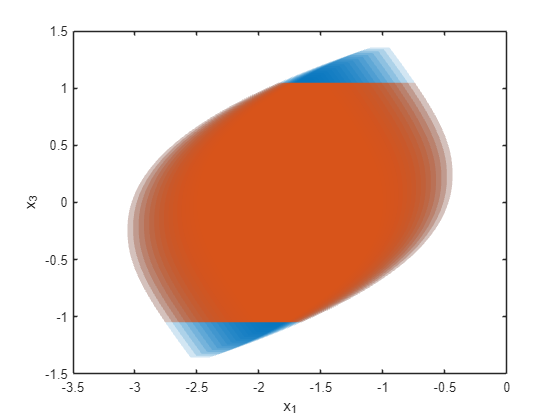

fig = figure();
axe = axes(fig);
hold(axe,"on");
plot(R,[1,3],"FaceAlpha",0.175,"EdgeAlpha",0);
hold(axe,"off");
box(axe,"on");
xlabel("x_1");
ylabel("x_3");

g = @(R)plot(R,[1,3], ...
    "FaceColor",'#D95319', ...
    "FaceAlpha",0.25, ...
    "EdgeAlpha",0);

hold(axe,"on");
cellfun(g,Rk);
hold(axe,"off");